# **디지털신호처리 ****HW#2**

Due date : 2021.12.22. 23:59

**이름**** : 김지원**

**학번**** : 201716155**

아래 문제에 대하여 MATLAB으로 구현하고 mlx파일을 본인의 Github에 업로드 하고 링크 주소를 적으세요.

**Repository 링크 : https://github.com/KimJiWon0/peace**

1. 이산 비주기 신호 $x\left\lbrack n\right\rbrack =\left\lbrace \underset{\uparrow }{1} ,2,2,1\right\rbrace$에 대하여 다음을 구하라.

1) 4점 DFT 및 IDFT를 수행하라. 그리고 DFT의 결과를 DTFT와 비교하라. 

x = [1,2,2,1];
N = 4;

k = 0:500:1000;
w = (pi/500)*k;

X = dft(x,N);
magX = abs(X);
phaX = angle(X)*180/pi;

X1 = idft(x,N);
magX1 = abs(X1);
phaX1 = angle(X1)*180/pi;



Y = x*(exp(-j*pi/500)).^(n'*k);
magY = abs(Y);
phaY = angle(Y);

X

X =    6.0000 + 0.0000i  -1.0000 - 1.0000i   0.0000 - 0.0000i  -1.0000 + 1.0000i


X1

X1 =    1.5000 + 0.0000i  -0.2500 + 0.2500i   0.0000 + 0.0000i  -0.2500 - 0.2500i


Y

Y =    6.0000 + 0.0000i   0.0000 - 0.0000i   6.0000 + 0.0000i


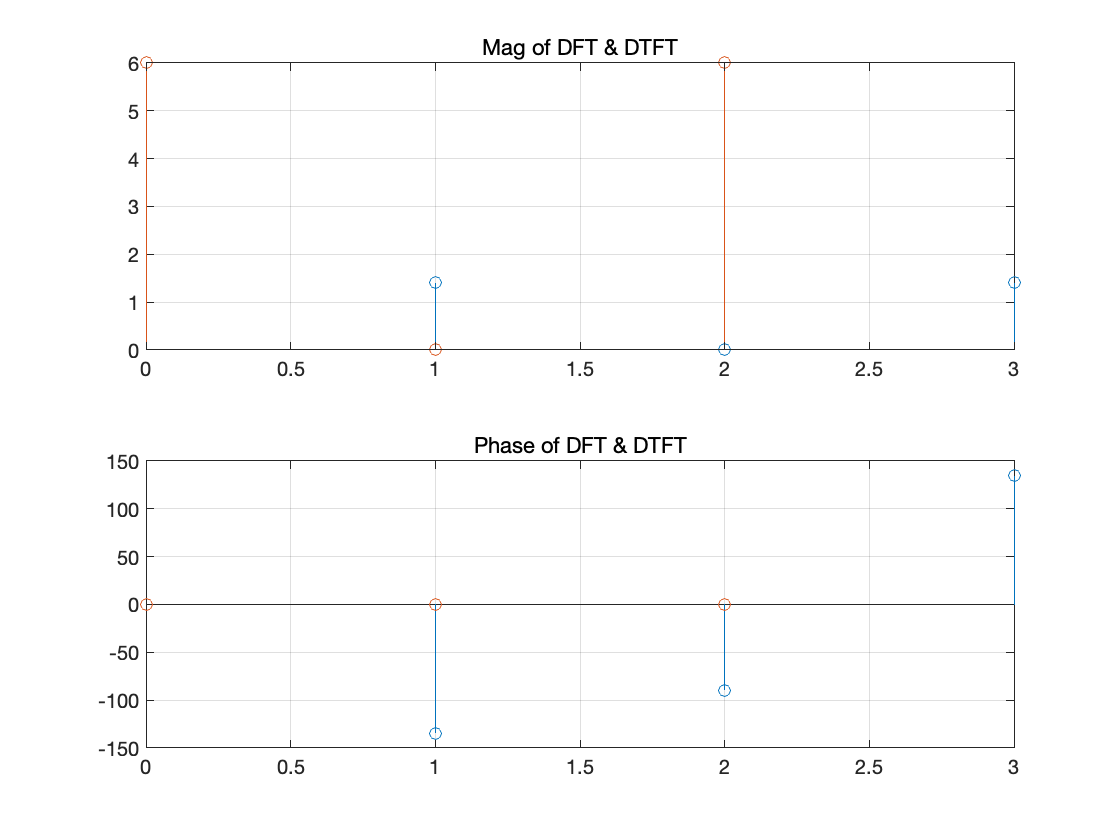

subplot(2,1,1);
stem(n,magX)
hold on
stem(w/pi,magY)
hold off
title('Mag of DFT & DTFT')
grid on

subplot(2,1,2);
stem(n,phaX)
hold on
stem(w/pi,phaY)
title('Phase of DFT & DTFT')
hold off
grid on

2) 영 채우기를 시행하여 같은 신호에 대해 16점 DFT 및 IDFT를 수행하라.


x = [1 2 2 1 0 0 0 0 0 0 0 0 0 0 0 0];
N=16;

X1 = dft(x,N);
magX1 = abs(X1);
phaX1 = angle(X1)*180/pi;

Y1 = idft(x,N);
magY1 = abs(Y1);
phaY1 = angle(Y1)*180/pi;

X1

X1 =    6.0000 + 0.0000i   4.6447 - 3.1035i   1.7071 - 4.1213i  -0.5727 - 2.8793i  -1.0000 - 1.0000i  -0.2557 - 0.0509i   0.2929 - 0.1213i   0.1838 - 0.2750i   0.0000 + 0.0000i   0.1838 + 0.2750i   0.2929 + 0.1213i  -0.2557 + 0.0509i  -1.0000 + 1.0000i  -0.5727 + 2.8793i   1.7071 + 4.1213i   4.6447 + 3.1035i


Y1

Y1 =    0.3750 + 0.0000i   0.2903 + 0.1940i   0.1067 + 0.2576i  -0.0358 + 0.1800i  -0.0625 + 0.0625i  -0.0160 + 0.0032i   0.0183 + 0.0076i   0.0115 + 0.0172i   0.0000 - 0.0000i   0.0115 - 0.0172i   0.0183 - 0.0076i  -0.0160 - 0.0032i  -0.0625 - 0.0625i  -0.0358 - 0.1800i   0.1067 - 0.2576i   0.2903 - 0.1940i


2. (P5.2) DFS의 정의를 사용하여 다음 주기 신호의 DFS 계수를 구하고, MATLAB을 사용하여 검증하라.

1) $\tilde{x_1 } \left(n\right)=\left\lbrace 4,1,-1,1\right\rbrace ,N=4$


$$\tilde{X} \left(0\right)=4{\cdot \textrm{WN}}^{0\cdot 0} +1\cdot {\textrm{WN}}^{1\cdot 0} -1\cdot {\textrm{WN}}^{2\cdot 0} +1\cdot {\textrm{WN}}^{3\cdot 0} =5$$



$$\tilde{X} \left(1\right)=4{\cdot \textrm{WN}}^{0\cdot 1} +1\cdot {\textrm{WN}}^{1\cdot 1} -1\cdot {\textrm{WN}}^{2\cdot 1} +1\cdot {\textrm{WN}}^{3\cdot 1} =5$$



$$\tilde{X} \left(2\right)=4{\cdot \textrm{WN}}^{0\cdot 2} +1\cdot {\textrm{WN}}^{1\cdot 2} -1\cdot {\textrm{WN}}^{2\cdot 2} +1\cdot {\textrm{WN}}^{3\cdot 2} =1$$



$$\tilde{X} \left(3\right)=4{\cdot \textrm{WN}}^{0\cdot 3} +1\cdot {\textrm{WN}}^{1\cdot 3} -1\cdot {\textrm{WN}}^{2\cdot 3} +1\cdot {\textrm{WN}}^{3\cdot 3} =5$$


xtilde1 = [4,1,-1,1];
N = 4;

Xtilde1 = dfs(xtilde1,N)

Xtilde1 =    5.0000 + 0.0000i   5.0000 + 0.0000i   1.0000 - 0.0000i   5.0000 + 0.0000i


2) $\tilde{x_2 } \left(n\right)=\left\lbrace 1,0,-1,-1,0\right\rbrace ,N=5$


$$\tilde{X} \left(0\right)=1{\cdot \textrm{WN}}^{0\cdot 0} +0\cdot {\textrm{WN}}^{1\cdot 0} -1\cdot {\textrm{WN}}^{2\cdot 0} -1\cdot {\textrm{WN}}^{3\cdot 0} \;+0\cdot {\textrm{WN}}^{4\cdot 0} =-1\;$$



$$\tilde{X} \left(1\right)=1{\cdot \textrm{WN}}^{0\cdot 1} +0\cdot {\textrm{WN}}^{1\cdot 1} -1\cdot {\textrm{WN}}^{2\cdot 1} -1\cdot {\textrm{WN}}^{3\cdot 1} \;+0\cdot {\textrm{WN}}^{4\cdot 1} =2\ldotp 618$$
 


$$\tilde{X} \left(2\right)=1{\cdot \textrm{WN}}^{0\cdot 2} +0\cdot {\textrm{WN}}^{1\cdot 2} -1\cdot {\textrm{WN}}^{2\cdot 2} -1\cdot {\textrm{WN}}^{3\cdot 2} \;+0\cdot {\textrm{WN}}^{4\cdot 2} =0\ldotp 382$$



$$\tilde{X} \left(3\right)=1{\cdot \textrm{WN}}^{0\cdot 3} +0\cdot {\textrm{WN}}^{1\cdot 3} -1\cdot {\textrm{WN}}^{2\cdot 3} -1\cdot {\textrm{WN}}^{3\cdot 3} \;+0\cdot {\textrm{WN}}^{4\cdot 3} =0\ldotp 382$$



$$\tilde{X} \left(4\right)=1{\cdot \textrm{WN}}^{0\cdot 4} +0\cdot {\textrm{WN}}^{1\cdot 4} -1\cdot {\textrm{WN}}^{2\cdot 4} -1\cdot {\textrm{WN}}^{3\cdot 4} \;+0\cdot {\textrm{WN}}^{4\cdot 4} =2\ldotp 618$$


xtilde2 = [1,0,-1,-1,0];
N = 5;

Xtilde2 = dfs(xtilde2,N)

Xtilde2 =   -1.0000 + 0.0000i   2.6180 + 0.0000i   0.3820 - 0.0000i   0.3820 + 0.0000i   2.6180 + 0.0000i


3.  (P5.10) 아래와 같이 주어진 유한 길이 신호를 고려하자.


$$x\left(n\right)=\left\lbrace \begin{array}{ll}
{\textrm{sinc}}^2 \left\lbrace \frac{\left(n-50\right)}{2}\right\rbrace  & 0\le n\le 100\\
0 & \textrm{otherwise}
\end{array}\right.$$


1) x(n)의 DFT X(k)를 구하라. (stem 함수를 사용하여) 그것의 크기 및 위상 그래프를 그려라. 

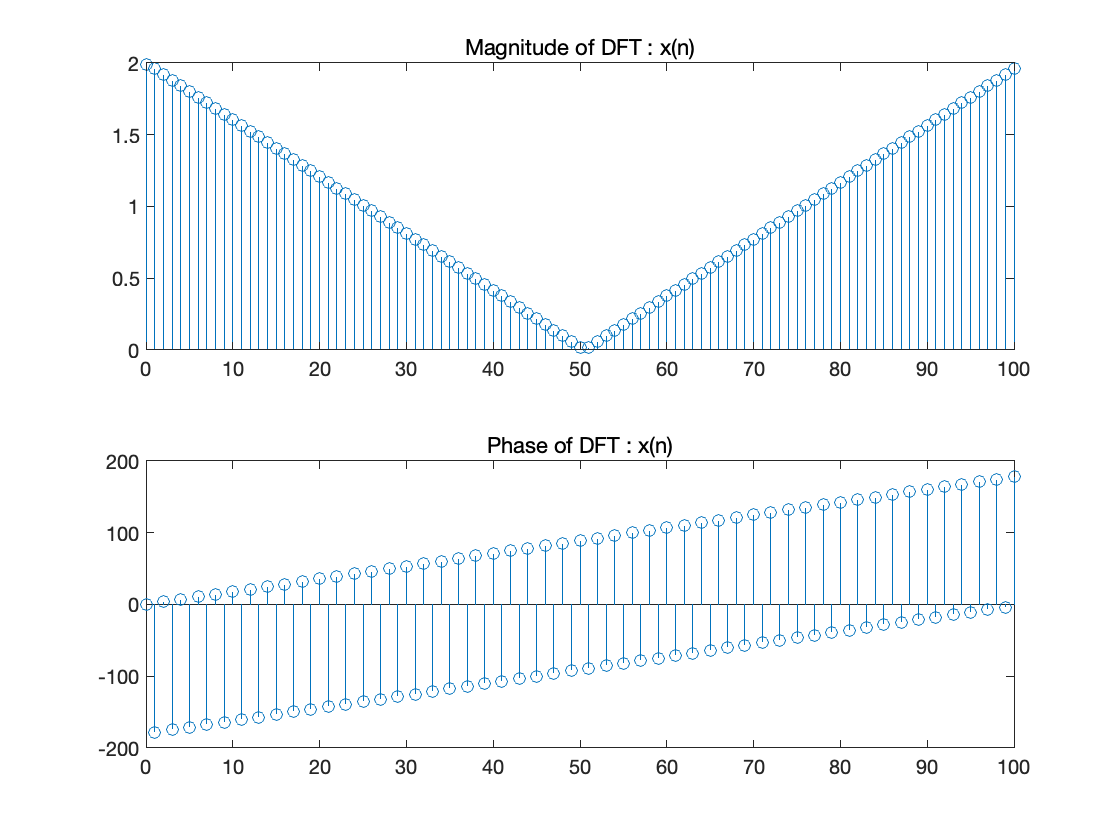

n = 0:100;
xn = sinc((n-50)/2).^2;
N = length(xn);
Xk = dft(xn,N);
k = 0:N-1;
magX = abs(Xk);
phaY = angle(Xk)*180/pi;
subplot(2,1,1)
stem(n,magX)
title('Magnitude of DFT : x(n)')
subplot(2,1,2)
stem(n,phaY)
title('Phase of DFT : x(n)')

2) MATLAB을 사용하여 x(n)의 DTFT $X\left(e^{j\omega } \right)$의 크기 및 위상 그래프를 그려라.

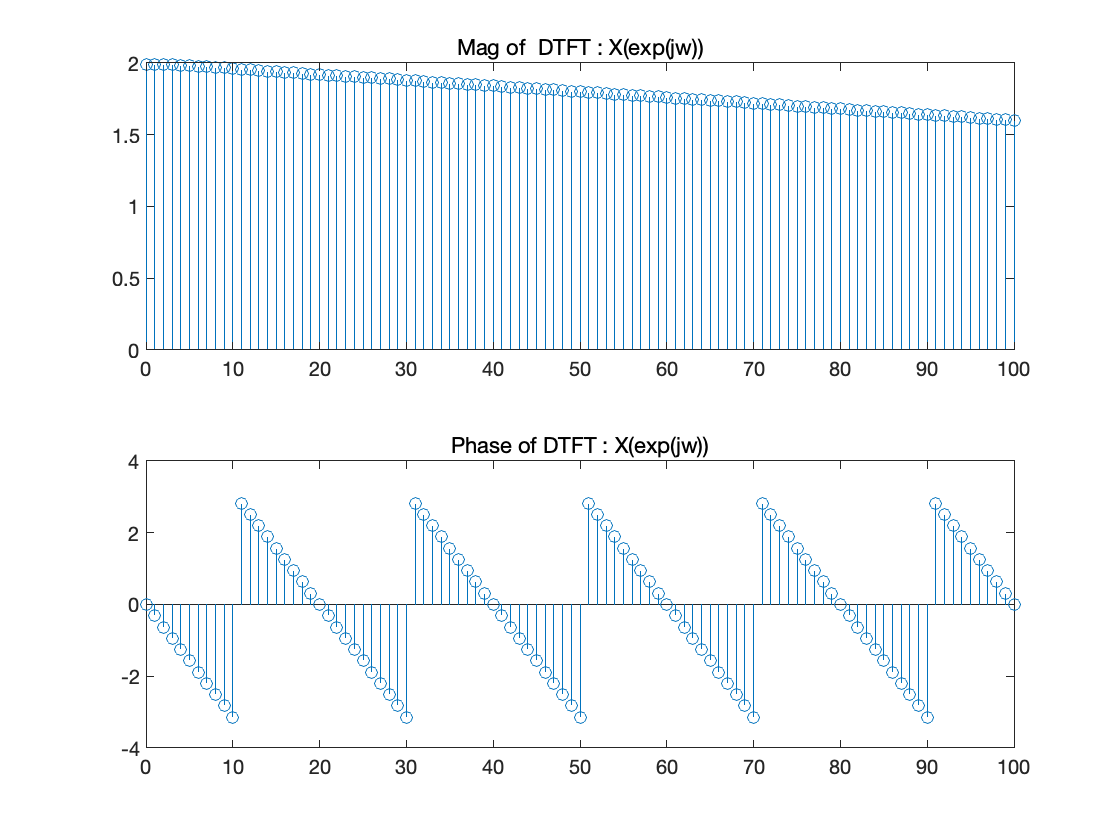

n = 0:100;
x = sinc((n-50)/2).^2; 
k = 0:100;
w = (pi/1)*k;
X = x*(exp(-j*pi/500)).^(n'*k);

magX1 = abs(X);
phaX1 = angle(X);

subplot(2,1,1);
stem(w/pi,magX1)
title('Mag of  DTFT : X(exp(jw))')

subplot(2,1,2);
stem(w/pi,phaX1)
title('Phase of DTFT : X(exp(jw))')

3) 위 DFT는 $X\left(e^{j\omega } \right)$의 샘플링된 변형임을 검증하라. hold 함수 (hold on;) 를 사용해서 두 그래프를 합치도록 한다.

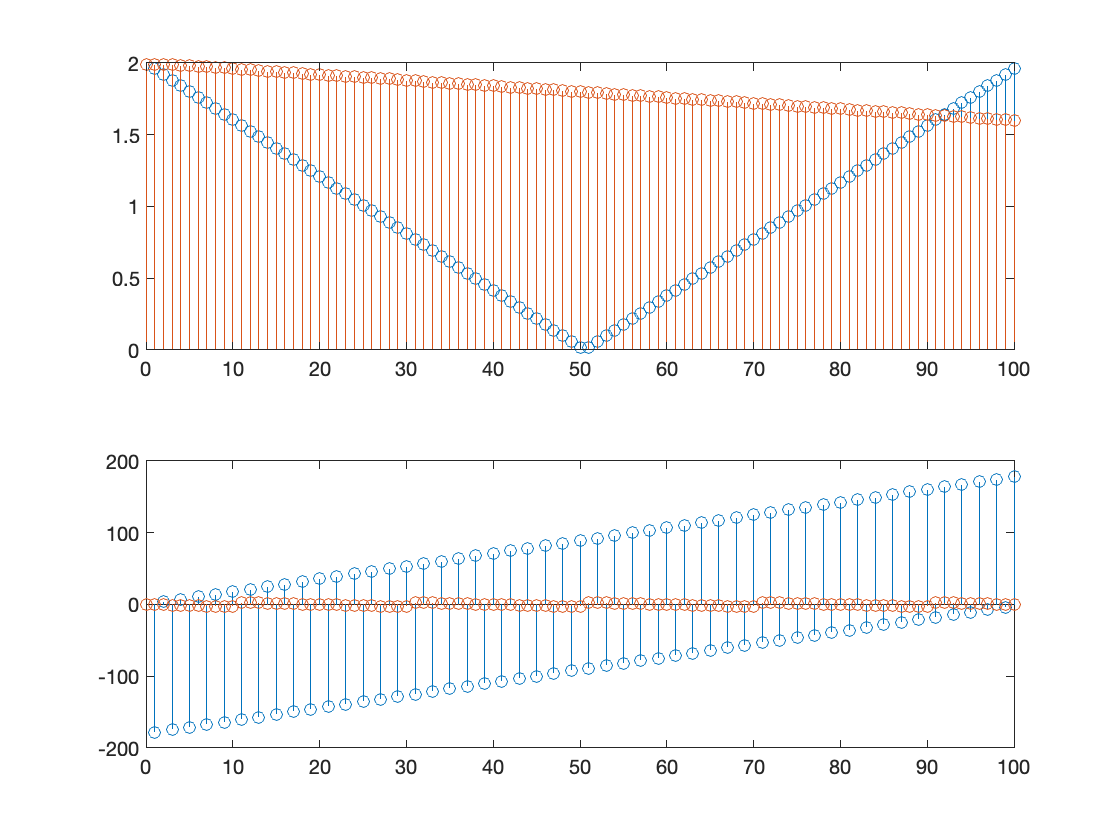


subplot(2,1,1)
stem(n,magX); hold on
stem(k,magX1)
hold off
subplot(2,1,2)
stem(n,phaY) ;hold on
stem(k,phaX1)
hold off

function [Xk] = dft(xn,N)

n = [0:1:N-1];
k = [0:1:N-1];
WN = exp(-j*2*pi/N);
nk = n'*k;
WNnk = WN.^nk;
Xk = xn * WNnk;

end

function [xn] = idft(Xk,N)

n = [0:1:N-1];
k = [0:1:N-1];
WN = exp(-j*2*pi/N);
nk = n'*k;
WNnk = WN .^ (-nk);
xn = (Xk *WNnk)/N;

end

function [Xk] = dfs(xn,N)

n = [0:1:N-1];
k = [0:1:N-1];
WN = exp(-j*2*pi/N);
nk = n'*k;
WNnk = WN.^nk;
Xk = xn*WNnk;

end

function idfs(Xk,N)

n = [0:1:N-1];
k = [0:1:N-1];
WN = exp(-j*2*pi/N);
nk = n'*k;
WNnk = WN.^(-nk);
xn = (Xk * WNnk)/N;

end

function [X] = dtft(x,N,w)

n = [0:1:N-1];
k = [0:1:N-1];
WN = exp(-j*2*pi/N);
nk = n'*k;
X = x*exp(-j*n'*w);
end



4) DFT $X\left(k\right)$로부터 DTFT $X\left(e^{j\omega } \right)$를 재구성할 수 있는가? 가능하다면, 재구성에 필요한 보간 공식을 구하라. 가능하지 않다면, 그 이유를 기술하라.

DFT $X\left(k\right)$로부터 DTFT $X\left(e^{j\omega } \right)$를 재구성할 수 있다.

공식은 다음과 같다.


$$X\left(e^{\textrm{jw}} \right)=\sum_{k=0}^{N-1} \tilde{X\left(k\right)} \frac{\;1-e^{-\textrm{jwN}} }{\;N\left\lbrace 1-e^{\textrm{j2}\pi \frac{k}{N}} \;e^{-\textrm{jw}} \right\rbrace }$$
  